# Práctica 4: Ecualización del histograma

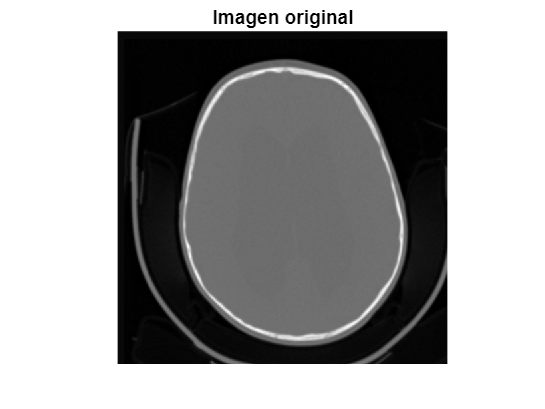

%Cargar imagen
imagen = imread("cerebro2.jpg");
imagen_rgb = rgb2gray(imagen);

% Mostrar imagen
imshow(imagen_rgb);
title('Imagen original')

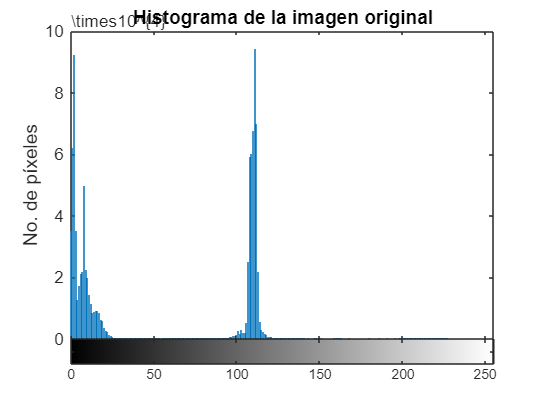


% Histograma
imhist(imagen_rgb);
xlim([0 255]);
ylim([0 100000]);
xlabel('Tonalidad');
ylabel('No. de píxeles');
title('Histograma de la imagen original');

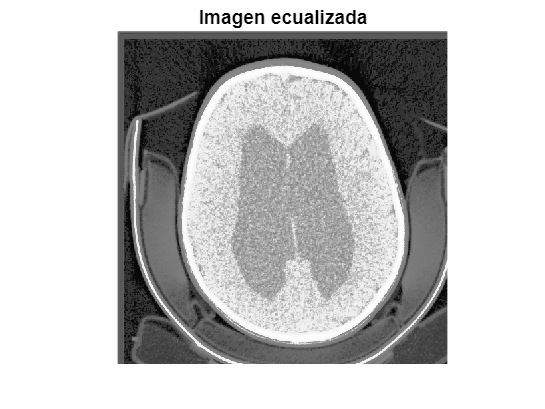


% Ecualización de la imagen
[alto, largo] = size(imagen_rgb);
Histograma = imhist(imagen_rgb) / (alto * largo);
Suma_Acomulada = cumsum(Histograma);
new_imagen = zeros(alto, largo);

for i = 1:alto
    for j = 1:largo
        new_imagen(i,j) = Suma_Acomulada(imagen_rgb(i,j) + 1) * 255;
    end
end

% Mostrar imagen
imshow(uint8(new_imagen));
title('Imagen ecualizada')

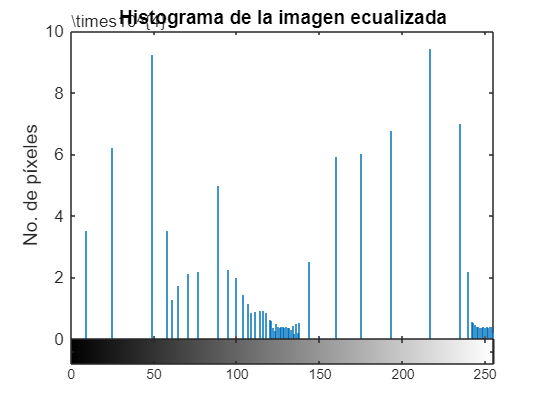


% Histograma
imhist(uint8(new_imagen), 256);
xlim([0 255]); 
ylim([0 100000]); 
xlabel('Tonalidad');
ylabel('No. de píxeles');
title('Histograma de la imagen ecualizada');